clc;
clear;

gnss_origin = [42.29322828071904, -71.26433857013662, 50];

tag_gnss_maps = [
    42.29330440324687, -71.26442138250495
    42.2934381493404, -71.26438618506542
    42.29353413949006, -71.26432834773381
    42.29358012016498, -71.26418765493307
    42.29364617294784, -71.26421425112251
    42.29362480297451, -71.2641274533543
    42.29373369699089, -71.26406691508114
    42.293800629254704, -71.26384894996616
    42.29378541164158, -71.2636193059333
    42.29365661112291, -71.26348053982403
    42.29355540678682, -71.26347651168008
    42.29332491558013, -71.26372656047833
    42.29324649784491, -71.26385982422015
    42.29319488913584, -71.2640152976136
    42.29317839266936, -71.26416410076888
    ];

posxy_meas = [
    -6.860 8.502
    -4.188 23.775
    0.847 34.282
    12.418 39.531
    10.230 46.645
    17.400 44.631
    22.329 56.340
    40.329 63.738
    59.013 62.425
    70.776 48.080
    71.186 36.752
    50.138 10.889
    39.286 2.134
    26.494 -3.701
    14.098 -5.531
    ];

tag_gnss_map_append = [tag_gnss_maps 50*ones(size(tag_gnss_maps,1),1)];
[posxy_gnss_x, posxy_gnss_y, posxy_gnss_alt] = latlon2local(tag_gnss_map_append(:,1),tag_gnss_map_append(:,2),tag_gnss_map_append(:,3), gnss_origin);
posxy_gnss = [posxy_gnss_x posxy_gnss_y];

posxy_meas_append = [posxy_meas 0*ones(size(posxy_meas,1),1)];
[lat_meas, lon_meas, alt_meas] = local2latlon(posxy_meas_append(:,1),posxy_meas_append(:,2),posxy_meas_append(:,3),gnss_origin);
latlon_meas = [lat_meas lon_meas];

norm_diff = vecnorm((posxy_gnss - posxy_meas)');

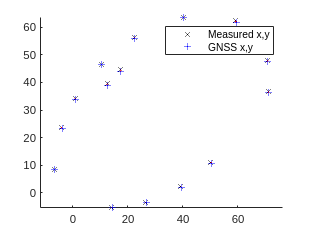

scatter(posxy_meas(:,1), posxy_meas(:,2), 'kx');
hold on;
scatter(posxy_gnss(:,1), posxy_gnss(:,2), 'b+');

for idx=1:size(posxy_gnss,1)
    xy_gnss = posxy_gnss(idx,:);
    xy_meas = posxy_meas(idx,:);
    plot([xy_gnss(1),xy_meas(1)], [xy_gnss(2) xy_meas(2)], '--r');
end

axis equal;
legend(["Measured x,y", "GNSS x,y"])
hold off;

gmaps_waypoints = [
42.293185209247184, -71.26428426120886;
42.29327790325564, -71.26437376918973;
42.293399067360994, -71.26436392331183;
42.29352023123324, -71.26429500216656;
42.29362550457538, -71.2641813270246;
42.29370694232076, -71.2640399044148;
42.29376189618846, -71.26387968512417;
42.293775800171126, -71.26369261344414;
42.29370230765663, -71.2635476105151;
42.293590413483365, -71.26350464668428;
42.293338293121586, -71.26365921428294;
42.29323930708792, -71.26380765649222;
42.293177102672026, -71.26396779857141;
42.29314843452921, -71.26413452183198;
42.29318413447862, -71.26428442651799;
];

gmaps_waypoints_append = [gmaps_waypoints 50*ones(size(gmaps_waypoints,1),1)];
[gmaps_waypoints_x, gmaps_waypoints_y, gmaps_waypoints_alt] = latlon2local(gmaps_waypoints_append(:,1),gmaps_waypoints_append(:,2),gmaps_waypoints_append(:,3), gnss_origin);
gmaps_waypoints_xy = [gmaps_waypoints_x gmaps_waypoints_y];